# Pitch Thrust from Yaw - Parameter Estimation

There is a reaction torque acting on the pitch from the yaw rotor. This lab shows how to find the thrust gain parameter that captures this effect.

## Concept Review

In the 2 DOF configuration, the motion of the pitch is affected by both rotors. The pitch or front rotor applies a direct thrust about the pitch axis but the yaw rotor generates a torque on the pitch axis as well. This can be represented by the following equation of motion (EOM):


$$J_p \ddot{\theta} + D_p \dot{\theta} + K_{sp}\theta =K_{pp} D_t V_p + K_{py} D_t V_y$$


where $\theta$ is the pitch angle, $J_p$ is the equivalent moment of inertia acting about the pitch axis, $D_p$ is the viscous damping, $K_{sp}$ is the stiffness, $K_{pp}$ is the force thrust gain acting on the pitch from the pitch rotor, $K_{py}$ is the thrust froce gain acting on the pitch from the yaw rotor, $D_t$ is the distance from the pivot point to the propeller, and$V_p$ is the voltage applied to the front pitch rotor motor. 

The pitch thrust $K_{pp}$, inertia, damping, and stiffness were identified in the *Pitch Parameter Estimation *lab. Because the yaw-axis is locked and we are only applying a thrust to the rear/yaw rotor, $V_p=0$, and the EOM becomes


$$J_p \ddot{\theta} + D_p \dot{\theta} + K_{sp}\theta =K_{py} D_t V_y$$


Given that the system starts at rest, the initial condition are zero and we have the following transfer function


$$\Theta(s) = \frac{K_{py} D_t V_y}
{J_p s^2+D_p s+K_{sp}}$$


We can use this transfer function to identify that pitch from yaw force gain $K_{py}$.

## Lab Procedure

Apply a voltage to the rear/yaw rotor and examine the reponse in the pitch to measure the thrust from the reaction torque. 

### Setup

- Make sure the Aero 2 has been tested as instructed in the Quick Start Guide. 

- Launch MATLAB and browse to the working directory that includes the Simulink models for this lab.

- Configure the Aero 2 in the 2 DOF Helicopter configuration: 

- **Unlock** the pitch axis and **lock **the yaw axis.

- Rear rotor 1 is **vertical **and front rotor 0 is **horizontal**.

- Mount weight on each rotor.

- Connect the USB cable to your PC/laptop.

- Connect the power and turn the power switch ON. The Aero base LED should be red.

### Lab 1: Get Open-Loop Response

The open-loop response can be obtained by running the `q_aero2_pitch_from_yaw_step `Simulink model shown in Figure 1 with QUARC. 

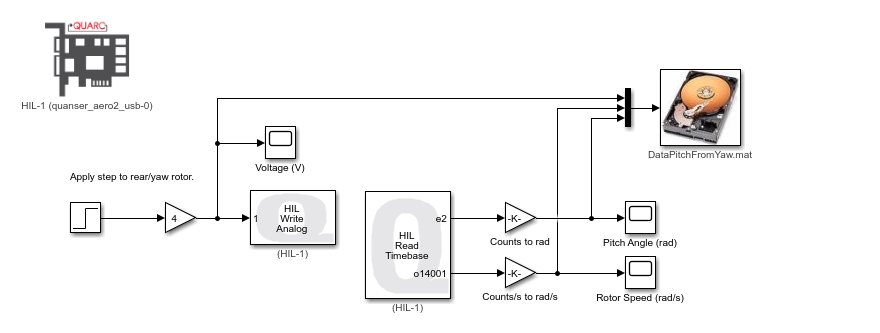

Figure 1 - Simulink model used with QUARC to apply a step to the rear/yaw rotor and measure the pitch angle.

The Simulink model uses the `HIL Write Analog `and `HIL Read Timebase `blocks from the *QUARC Targets *library to apply a voltage to the rear yaw rotor and measure the corresponding pitch angle response. The response is saved into a MATLAB *.mat files using the `To Host File `block. This can then be used to plot the results and perform the parameter estimation analysis. 

Build and run the following Simulink model in QUARC by clicking on the *Monitor & Tune* button.

% Load Simulink model
open("q_aero2_pitch_from_yaw_step.slx");

Figure 2 shows the pitch angle response and applied voltage in the scopes. 

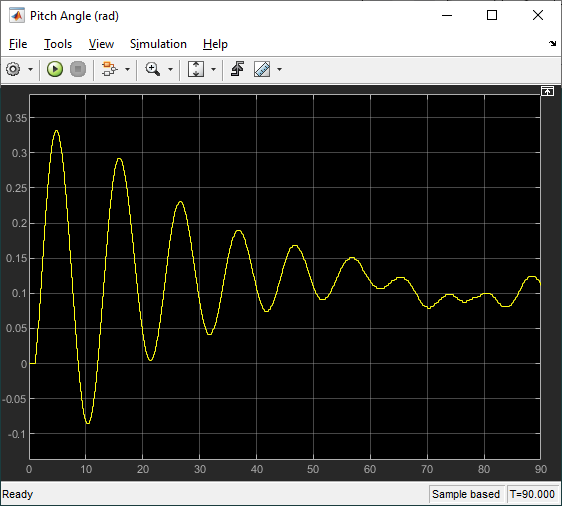 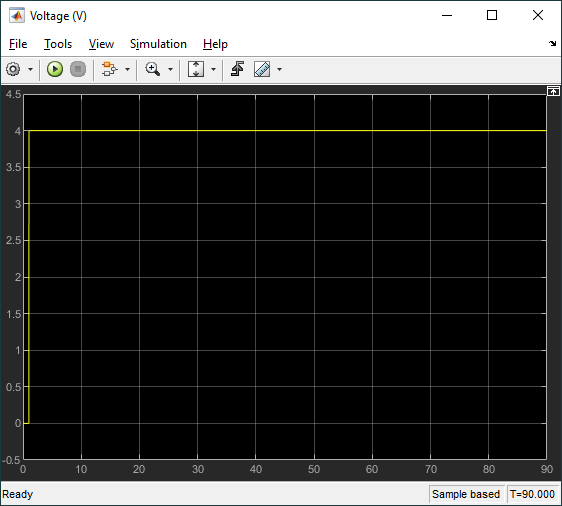

Figure 2 - Pitch angle response from applying a step to the rear yaw rotor. 

Plot measured response 

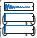

% Load measured data from past run
load('DataPitchFromYaw.mat');
% store in variables
t = PitchFromYaw(1,:); % time (s)
Vy = PitchFromYaw(2,:); % yaw/rear motor voltage (V)
wm_y= PitchFromYaw(3,:); % yaw/rear rotor speed (rad/s)
theta = PitchFromYaw(4,:); % pitch angle (rad)
%
subplot(3,1,1);
plot(t,theta);
title('Measured Pitch Angle');
ylabel('Pitch (rad)');
subplot(3,1,2);
plot(t,wm_y);
ylabel('Yaw Rotor (rad/s)');
subplot(3,1,3);
plot(t,Vy);
ylabel('Yaw Motor (V)');
xlabel('time (s)');

### Lab 2: Finding the Thrust Gain

Applying a step input with an amplitude of $V_{y0}$ to the yaw rotor  


$$\Theta(s)= \frac{ \frac{D_tK_{py}}{J_p} } {s^2 + \frac{D_p}{J_p}s + \frac{K_{sp}}{J_p}
}\frac{V_{y0}}{s}$$


Using the Final-Value Theorem (FVT), the steady-state angle is


$$\theta_{ss} = \lim_{s \to 0} \frac{ \frac{D_tK_{py}}{J_p} } {s^2 + \frac{D_p}{J_p}s + \frac{K_{sp}}{J_p}}V_{y0}= \frac{D_t K_{py}}{K_{sp}}V_{y0}$$


Solving for the thrust


$$K_{py} = \frac{\theta_{ss}K_{sp}}{D_t V_{y0}}$$


Load the AERO 2 Parameters

aero2_parameters;

Load stiffness found in the *Pitch Parameter Estimation *lab.

% Stiffness (N-m/V)
% Ksp = 0.00884;
Ksp = 0.0132;

Find the pitch from yaw thrust force gain.

% steady-state pitch angle (rad)
% theta_ss = 0.122;
theta_ss = 0.0785;
% yaw step input (V)
Vp0 = max(Vy);
% pitch thrust from yaw (N/V)
Kpy = theta_ss * Ksp / Dt / Vp0

Kpy = 0.0015

The measured cross-thrust acting on the pitch-axis from the yaw/back rotor is

$K_{py}=4.0259\times10^{-4}$ N/V